# piDMD w/ dimensional reduction via LSUN for Conservative systems

References

- Baddoo Peter J., Herrmann Benjamin, McKeon Beverley J., Nathan Kutz J. and Brunton Steven L. 2023Physics-informed dynamic mode decompositionProc. R. Soc. A.4792022057620220576, [http://doi.org/10.1098/rspa.2022.0576](http://doi.org/10.1098/rspa.2022.0576)

- Brunton, S. L., & Kutz, J. N. (2022). *Data-Driven Science and Engineering: Machine Learning, Dynamical Systems, and Control* (2nd ed.). Cambridge: Cambridge University Press.

- Kutz JN, Brunton SL, Brunton BW, Proctor JL. 2016 *Dynamic mode decomposition: data-driven modeling of complex systems*. Philadelphia, PA: SIAM.

clear 
close all

## Parameter Setup

nModes4PODtrunc = 15; % 15/151 ~ 0.0993
nCoefs4LSUNtrunc = 2;  
nrows = 199

nrows = 199

ncols = 449;

## Source Data Preparation

load("../../../data/databook_DATA/DATA/VORTALL");
ut = reshape(VORTALL,nrows,ncols,[]);

## Source Data Visualization

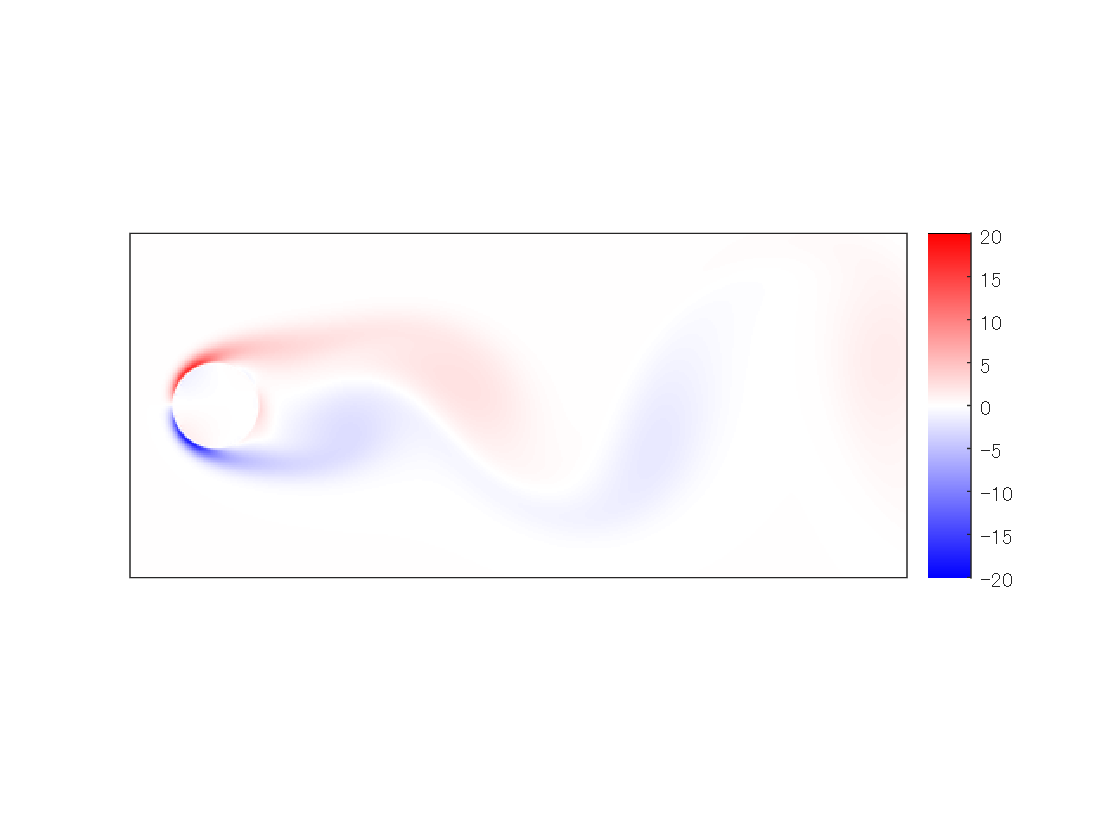

clims = 1.1*[min(ut,[],'all') max(ut,[],'all')];
nFrames = size(ut,3);
him = [];
for iFrame = 1:nFrames
    x = ut(:,:,iFrame);
    him = mycylinderplot_(him,x,clims);
    if iFrame == 1
        hcb = colorbar;
        hcb.Box = "off";
    end
    drawnow
end

% exportgraphics

% POD truncation
Xorg = reshape(ut,[],size(ut,3));
Xo = Xorg(:,1:end-1);
%Yo = Xorg(:,2:end);
[Psiorg,Sorg,Vorg] = svds(Xo,nModes4PODtrunc);
Atorg = Sorg*Vorg';

% Approximation
Xtilde = Psiorg*Atorg;
mean((Xo-Xtilde).^2,'all')

ans = 3.2466e-05

## Noisy Data Preparation

Noise energy set to 20% of signal energy

varu = var(ut,0,'all');
varw = 0.2*varu; 
sigmaw = sqrt(varw);
vt = ut + sigmaw * randn(size(ut),'like',ut);

## Noisy Data Visualization

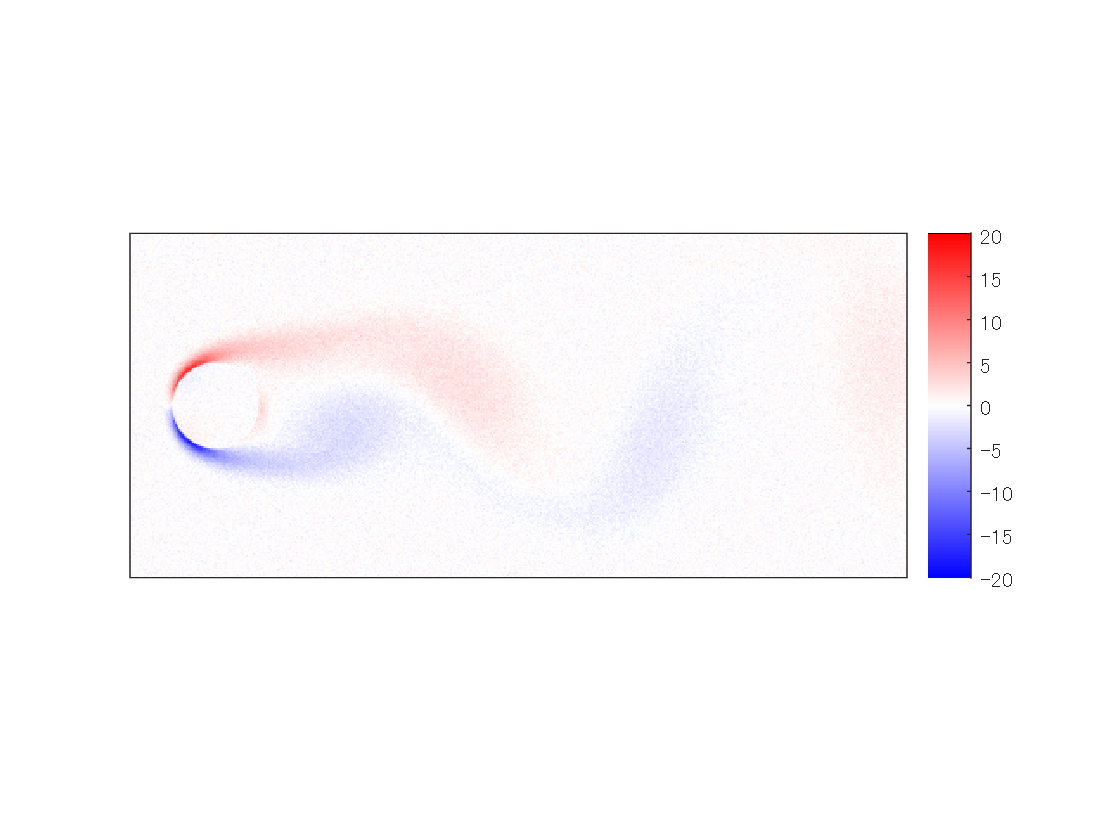

him = [];
for iFrame = 1:nFrames
    x = vt(:,:,iFrame);
    him = mycylinderplot_(him,x,clims);
    if iFrame == 1
        hcb = colorbar;
        hcb.Box = "off";
    end
    drawnow
end

% exportgraphics

## Experiments

### Define data matrix

Xnoisy = reshape(vt,[],size(vt,3));
Xn = Xnoisy(:,1:end-1);
Yn = Xnoisy(:,2:end);

## exact DMD w/ leading POD truncation

[exA, exVals] = piDMD(Xn,Yn,'exact',nModes4PODtrunc); % Original exact DMD

## piDMD w/ leading POD mode truncation

- Apply POD

- Project data onto the leading POD modes

- Apply piDMD

### piDMD w/ inside POD truncation (for validation)

[piA0, piVals0] = piDMD(Xn,Yn,'orthogonal',nModes4PODtrunc); % Original piDMD

### piDMD w/ outside POD truncation

% Project X and Y onto principal components
[Psi,~,~] = svds(Xn,nModes4PODtrunc);
Xproj= Psi'*Xn; Yproj = Psi'*Yn; 
[piA1, piVals1] = piDMD(Xproj,Yproj,'orthogonal'); 
piApod = @(x) Psi*piA1(Psi'*x);

% Assesment 
assert(mean((piVals0-piVals1).*conj(piVals0-piVals1))<1e-9)
assert(mean((piApod(Xn)-piA0(Xn)).^2,'all')<1e-9)

## piDMD w/ dimensional reduction via LSUN

- Train LSUN 

- Project data onto the LSUN feature space

- Apply piDMD

### Train LSUN

% TODO: Train 2-D LSUN w/ vt
nDecs = [4 4];
nrowsext = ceil(nrows/nDecs(1))*nDecs(1);
ncolsext = ceil(ncols/nDecs(2))*nDecs(2);
% Pad zeros to make the size multiples of nDecs.
vtpad = padarray(vt,[nrowsext ncolsext]-[nrows ncols],0,'post');

% TODO: Define the LSUN analyzer and synthesizer
analyzer_ = @(x) reshape(x,1,[]);
synthesizer_ = @(x) x;

### Project X and Y onto the LSUN feature space

% Project X and Y onto the LSUN feature space
Xlsun = zeros(nrowsext*ncolsext,nFrames-1,'like',vtpad);
Ylsun = zeros(nrowsext*ncolsext,nFrames-1,'like',vtpad);
for iFrame = 1:nFrames-1
    Xlsun(:,iFrame) = analyzer_(vtpad(:,:,iFrame)); 
    Ylsun(:,iFrame) = analyzer_(vtpad(:,:,iFrame+1)); 
end

### Apply piDMD

[piA2, piVals2] = piDMD(Xlsun,Ylsun,'orthogonal'); 
piAlsun = @(x) synthesizer_(piA2(analyzer_(x)));

## Plot some results

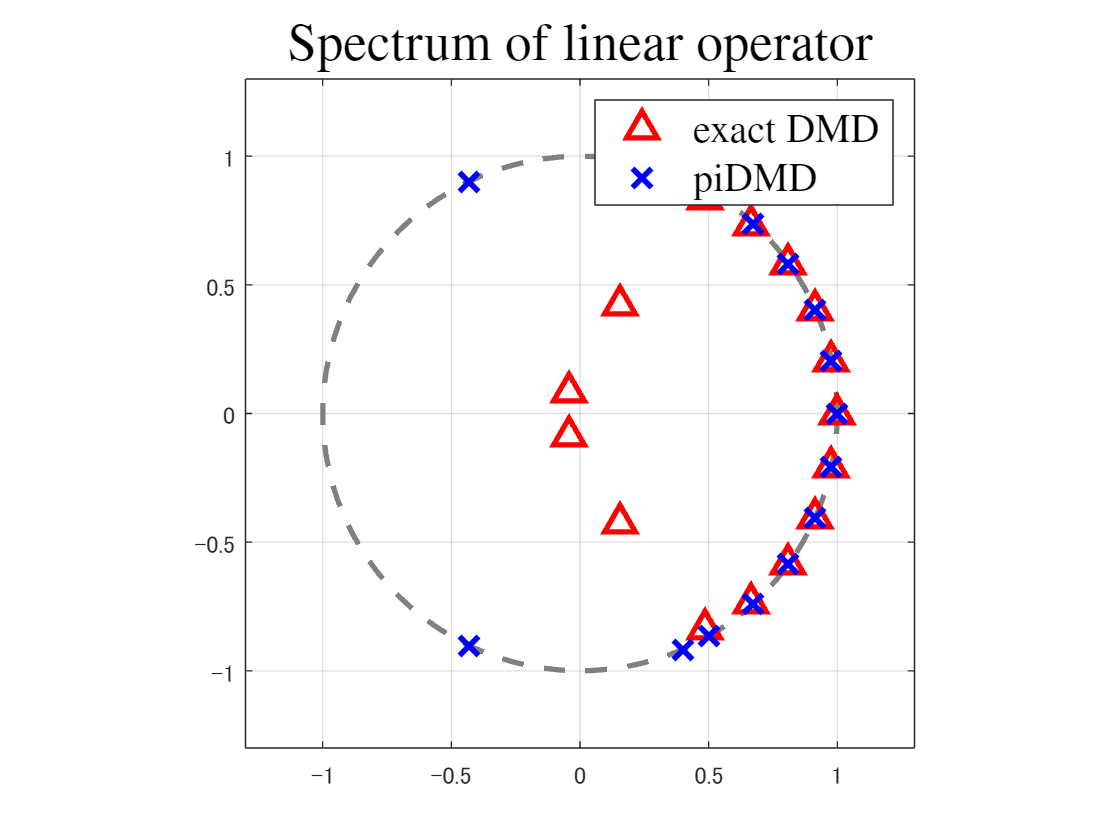

FS = 'FontSize'; IN = 'Interpreter'; LT = 'Latex'; MS = 'MarkerSize'; LW = 'LineWidth';
%
figure
clf
plot(exp(1i*linspace(0,2*pi)),'--','Color',[1 1 1]*.5,LW,2)
hold on
p2 = plot((exVals)+1i*eps,'r^',LW,2,MS,10);
p3 = plot((piVals1)+1i*eps,'bx',LW,2,MS,10);

grid on; axis equal; hold off
axis(1.3*[-1,1,-1,1])

legend([p2,p3],{'exact DMD','piDMD'},FS,15,IN,LT)
title('Spectrum of linear operator',FS,20,IN,LT)

## Local functions

### Definition of Drawing Function

function him = mycylinderplot_(him,x,clims)
if isempty(him)
    figure
    him = imagesc(x,clims);
    axis equal
    axis tight
    ax = gca;
    ax.XTick = [];
    ax.YTick = [];
    cmap = zeros(256,3);
    cmap(128:255,1) = 1;
    cmap(1:127,3) = 1;
    hsv = rgb2hsv(permute(cmap,[1 3 2]));
    hsv(:,2) = [254:-2:0 1:2:255].'/255;
    cmap = ipermute(hsv2rgb(hsv),[1 3 2]); 
    colormap(cmap)
else
    him.CData = x;
end
end

### Definition of Drawing POD mode trajectories

function mypodmodetraj(At,modes)
tiledlayout(length(modes),1);
for mode = modes
    ak = At(mode,:);
    %
    nexttile
    plot(ak)
    ax = gca;
    ax.XLim = [0 size(ak,2)];
    ylabel("mode " + mode)
    if mode == modes(end)
        xlabel("time");
    else
        ax.XTick = [];
    end
end
end